Validation of parameters presented in the article:

clc;
clear all;

% Параметры двигателя постоянного тока
Kv = 0.0097342;  % Постоянная ЭДС двигателя, [В]
R = 0.335;   % Сопротивление двигателя,  [Ом]
Kt = Kv;      % Постоянная двигателя,     [Н*м/A]
Ti = 1e-3*9.73;  % Временная константа по моменту, [Н/А]

% Параметры системы
d = 0.11256;  % Расстояние от центра базы до центра колеса, [м]
r = 0.03;     % Радиус колеса, [м]
l = 21;       % Коэффицент редуктора
M = 6.450;    % Масса робота, [кг]
J = 0.05;    % Моменты инерции платформы робота,    [кг*м^2]
Bvx = 0.5082;  % Коэффициент вязкого трения вдоль v,  [Н*с/м]
Bvy = 0.4870; % Коэффициент вязкого трения вдоль vn, [Н*с/м]
Bw = 0.0130;  % Коэффициент вязкого трения вдоль w,  [Н*м*с/рад]
Cvx = 1.9068;  % Коэффициент Кулоновского трения вдоль v,  [Н]
Cvy = 2.0423; % Коэффициент Кулоновского трения вдоль vn, [Н]
Cw = 0.0871;  % Коэффициент Кулоновского трения вдоль w,  [Н*м]

% Линейная модель без Кулоновского трения

% Компактная переменная: выходной ток двигателя - сила на колесе
Kmotor = Kt*l/(r);

A = [0 0 0    1     0    0         % A - Матрица динамики системы
     0 0 0    0     1    0  
     0 0 0    0     0    1  
     0 0 0 -Bvx/M    0    0 
     0 0 0    0 -Bvy/M   0    
     0 0 0    0     0 -Bw/J ];
 
B = [    0               0               0        
         0               0               0
         0               0               0
-cos(pi/6)*Kmotor/M      0      cos(pi/6)*Kmotor/M
 -cos(pi/3)*Kmotor/M  Kmotor/M  -cos(pi/3)*Kmotor/M
     -d*Kmotor/J      -d*Kmotor/J      -d*Kmotor/J];
 
C = [1 0 0 0 0 0                     % C - Матрица выходного сигнала
     0 1 0 0 0 0 
     0 0 1 0 0 0 
     0 0 0 1 0 0  
     0 0 0 0 1 0 
     0 0 0 0 0 1 ];
 
 D = [0 0 0                         % D - Матрица прямой связи
      0 0 0
      0 0 0
      0 0 0
      0 0 0
      0 0 0];
 
sysC = ss(A,B,C,D,'StateName',{'X' 'Y' 'Theta' 'Vx' 'Vy' 'W'}, ...
    'InputName',{'I1' 'I2' 'I3'}, 'OutputName', {'X' 'Y' 'Theta' 'Vx' 'Vy' 'W'}');

% Дискретизация системы
Ts = 0.02;  % Time step, [c]

sysD = c2d(sysC,Ts);
[Phi,Gam,Cd,Dd] = ssdata(sysD);

% Наблюдаемость системы - to be discussed

% Аугментация системы, добавление интегрирующих состояний по x, y, theta
Phi_aug = [Phi zeros(6,3)
           Cd(1:3,1:6) eye(3)];

Gam_aug = [Gam
           zeros(3,3)];

Cd_aug = [Cd zeros(6,3)
          zeros(3,6) eye(3)];

Dd_aug = zeros(9,3);

sysD_aug = ss(Phi_aug, Gam_aug, Cd_aug, Dd_aug, Ts,'StateName',{'X' 'Y' 'Theta' 'Vx' 'Vy' 'W' 'Int_Err_X' 'Int_Err_Y' 'Int_Err_Theta'}, ...
    'InputName',{'I1' 'I2' 'I3'}, 'OutputName', {'X' 'Y' 'Theta' 'Vx' 'Vy' 'W' 'Int_Err_X' 'Int_Err_Y' 'Int_Err_Theta'}');

% Управляемость системы
Wc = ctrb(Phi_aug, Gam_aug);
if rank(Wc) == length(Phi_aug)
    disp('The system is controllable!');
else 
    disp('The system is not controllable!');
end

The system is controllable!



% Синтез LQR контроллера
% Задание максимальных отклонений по параметрам
% Динамика системы
m_x = 0.00001;         % [м]
m_y = 0.00001;         % [м]
m_th = deg2rad(0.03);  % [рад]
m_v = 0.05;         % [м/с] m_v = 0.0001;
m_vn = 0.05;        % [м/с]
m_w = 0.05;         % [м/с]
m_err_x = 0.001;       
m_err_y = 0.001;
m_err_th = 0.005;
% Управление системы
u_f = 0.0004;         % [A]

Q = diag([1/m_x^2 1/m_y^2 1/m_th^2 1/m_v^2 1/m_vn^2 1/m_w^2 1/m_err_x^2 1/m_err_y^2 1/m_err_th^2]);

R = diag([1/u_f^2 1/u_f^2 1/u_f^2]);

[K_aug, S, e] = dlqr(Phi_aug, Gam_aug, Q, R);

% Разделим контроллер на две части
K_fsfb = K_aug(1:3, 1:6);           % Feedback part
K_int = K_aug(1:3, 7:9);             % Integral part

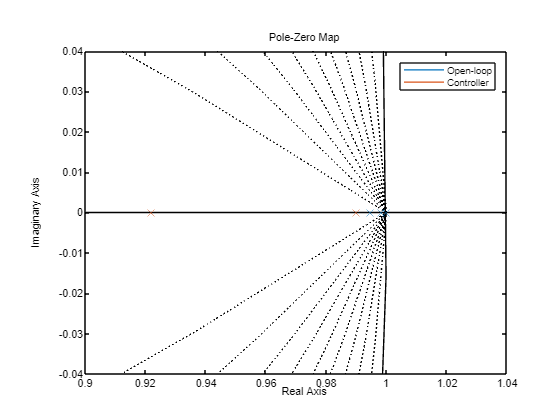

% Анализ динамики и стабильности системы
% Корни замкнутой системы с контроллером
Eig = eig(Phi_aug - Gam_aug*K_aug);        
% Корневой годограф
figure('Name', 'Poles of the systems');
opt = pzoptions;
opt.Grid = 'on';
opt.IOGrouping = 'all';
opt.Xlim = [0.9 1.04];
opt.Ylim = [-0.04 0.04];
pzplot(sysD_aug, feedback(sysD_aug,K_aug), opt);
legend('Open-loop','Controller');

% Save controllers for ROS
csvwrite('C:\Users\user\OneDrive\LQR\omni_dynamic_controller\scripts\K_fsfb.csv',K_fsfb)
csvwrite('C:\Users\user\OneDrive\LQR\omni_dynamic_controller\scripts\K_int.csv',K_int)